# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 07-Nov-2022 01:05:43

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 15);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Re", "S", "Ri", "xc", "yc", "Nu", "T", "Pi", "Po", "Nuw_c", "Tw_c", "Piw_c", "Pow_c", "delPdelPo", "delNudelNuo"];
opts.VariableTypes = ["double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Re", "S"], "EmptyFieldRule", "auto");

% Import the data
data_vis = readtable("D:\Matlab Drive\Research\All data merged ready for training.csv", opts)

data_vis = 10920×15 table
    Re    S     Ri      xc     yc       Nu         T         Pi        Po       Nuw_c      Tw_c      Piw_c      Pow_c     delPdelPo    delNudelNuo
    __    _    _____    ___    ___    ______    _______    ______    _______    ______    _______    ______    _______    _________    ___________

    50    0      0.1    0.2    0.2    2.2891    0.14015    4.9081    0.23716    2.2656    0.13955     2.992    0.23141      1.692         1.0104  
    50    0    0.595  


data_vis.S = renamecats(data_vis.S,'0','ψ=0');
data_vis.S = renamecats(data_vis.S,'0.5','ψ=0.5');
data_vis.S = renamecats(data_vis.S,'1','ψ=1');
data_vis.S = renamecats(data_vis.S,'2','ψ=2')

data_vis = 10920×15 table
    Re     S      Ri      xc     yc       Nu         T         Pi        Po       Nuw_c      Tw_c      Piw_c      Pow_c     delPdelPo    delNudelNuo
    __    ___    _____    ___    ___    ______    _______    ______    _______    ______    _______    ______    _______    _________    ___________

    50    ψ=0      0.1    0.2    0.2    2.2891    0.14015    4.9081    0.23716    2.2656    0.13955     2.992    0.23141      1.692         1.0104  
    50    ψ=0   

## Clear temporary variables

clear opts

**Data Visualization**

Nu

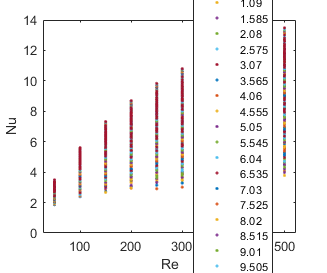

gscatter(data_vis.Re,data_vis.Nu,data_vis.Ri)
xlabel('Re')
ylabel('Nu')

Nubin=1:0.5:14

Nubin =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000


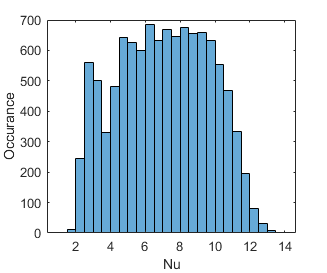

histogram(data_vis.Nu,Nubin)
xlabel('Nu')
ylabel('Occurance')

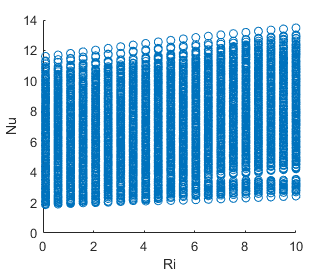

scatter(data_vis.Ri,data_vis.Nu)
xlabel('Ri')
ylabel('Nu')

**Re vs Nu for different Ri x and y position**

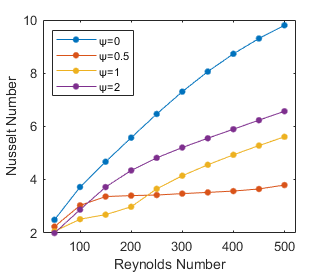

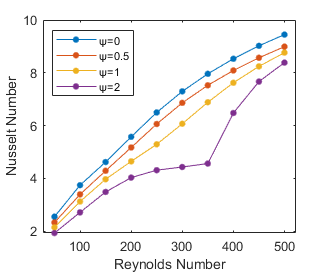

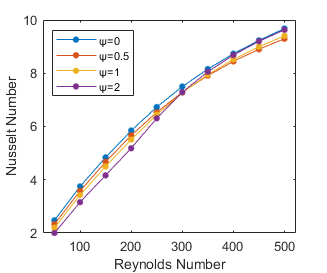

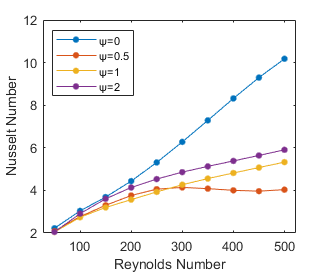

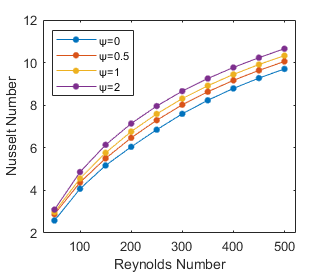

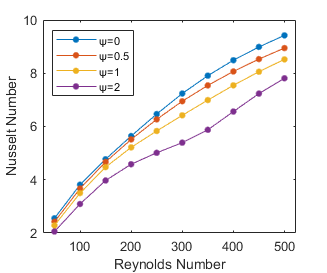

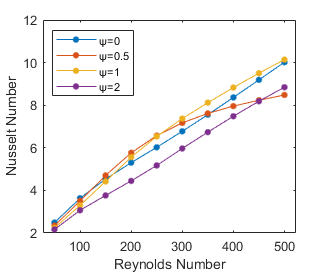

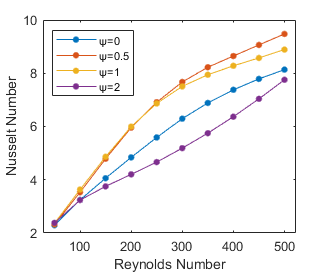

Riset=[1.09,3.07,8.515];
xcset=[0.2,0.5,0.8];
ycset=[0.2,0.5,0.8];
for i=Riset
    for j=xcset
        for k=ycset
            f=figure();
            data2=data_vis(data_vis.Ri==i& data_vis.xc==j & data_vis.yc==k,:);
            s=gscatter(data2.Re,data2.Nu,data2.S);
            set(s,'linestyle','-')
            xlabel('Reynolds Number')
            ylabel('Nusselt Number')
%             str=sprintf('Nusselt number variation for different Reynolds numbers for different Ψ for Ri=%.3f Position xc=%.2f and yc=%.2f',i,j,k);
%             title(str,'Position', [280.2, -0.1, 0]);
            legend('location','northwest');
            name1=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Re/ Nu vs Re, Ri= %.3f, xc=%.2f, yc=%.2f.bmp',i,j,k);
            saveas(gcf,name1)
        end
    end
end

**Ri vs Nu for diff para**

Reset=[50,300,500];
xcset=[0.2,0.5,0.8];
ycset=[0.2,0.5,0.8];
for i=Reset
    for j=xcset
        for k=ycset
            g=figure();
            data2=data_vis(data_vis.Re==i& data_vis.xc==j & data_vis.yc==k,:);
            s=gscatter(data2.Ri,data2.Nu,data2.S);
            set(s,'linestyle','-')
            xlabel('Richardson Number')
            ylabel('Nusselt Number')
%             str=sprintf('Nusselt number variation for different Richardson numbers for different Ψ for Re=%d Position xc=%.2f and yc=%.2f',i,j,k);
%             title(str);
            legend('location','northwest');
            name2=sprintf('D:/Matlab Drive/Research/Figure/Nu vs Ri/ Nu vs Ri, Re= %d, xc=%.2f, yc=%.2f.bmp',i,j,k);
            saveas(gcf,name2)
        end
    end
end

Dot indexing is not supported for variables of this type.